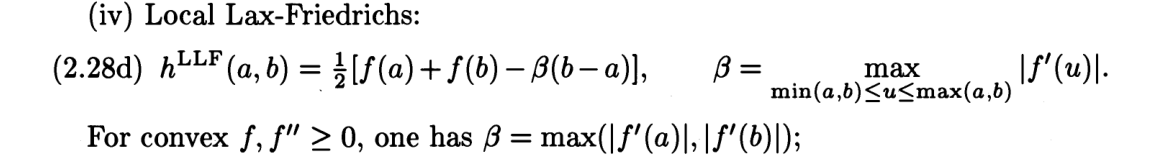

function m_Hflux = Getflux(Upm)
num = size(Upm,1);
m_Hflux = zeros(num+1,1);
fu

LLFflux = @(a,b) 0.5 * ( f(a) + f(b) - max(abs(df(a)),abs(df(b))) * (b - a) );    % 数值通量公式

for i = 1:num+1
    if i == 1
        m_Hflux(i) = LLFflux(Upm(end,2),Upm(i,1));
    elseif i == num+1
        m_Hflux(i) = LLFflux(Upm(i-1,2),Upm(1,1));
    else
        m_Hflux(i) = LLFflux(Upm(i-1,2),Upm(i,1));
    end
end

end
